# Invers Kinematics: Key ideas

## Call a simple Two Link 

2R robot arm

clear
mdl_twolink
twolink

### Plotting twolink

subplot(121)
twolink.plot([pi/6 pi/5],'view',[-40 25])
subplot(122)
twolink.plot([pi/6 pi/5])
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

### Forward Kinematics of Two Link

syms theta_1 theta_2 L_1 L_2 real
FK2L_Hand=simplify(troty(theta_1)*transl(L_1,0,0)*troty(theta_2)*transl(L_2,0,0))
twolink.links(1, 1).a=L_1;
twolink.links(1, 2).a=L_2;
FK2L_RTB=simplify(twolink.fkine ([theta_1 theta_2]))

### The equation system to solve

syms x z real %position of the {EE}
e1 = x == FK2L_RTB.t(1)
e2 = z == FK2L_RTB.t(3)

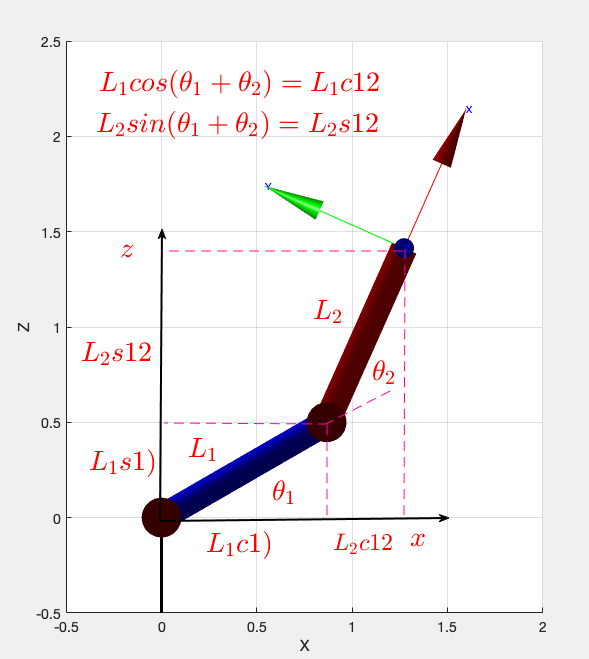

## Invers Kinematics by hand.

### Generate a known solution

clear
mdl_twolink
twolink.links(1, 1).a=1.5;
twolink.links(1, 2).a=1;
FD=twolink.fkine([pi/6 pi/5]);
XYZ=FD.t
Rotation=FD.R
L1=twolink.links(1, 1).a
L2=twolink.links(1, 2).a

### Apply the theory

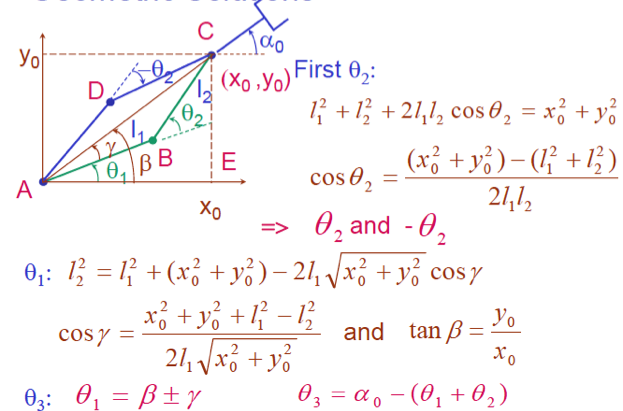

theta_2=acos(((XYZ(1)^2+XYZ(3)^2) -(L1^2+L2^2))/(2*L1*L2))
beta=atan2(XYZ(3),XYZ(1))
gamma=acos((XYZ(1)^2+XYZ(3)^2+L1^2-L2^2)/(2*L1*sqrt((XYZ(1)^2+XYZ(3)^2))))
theta_1_1=beta+gamma
theta_1_2=beta-gamma
pi/6
pi/5

### Testing solutions. See {EE}

XYZ
FD=twolink.fkine([pi/6 pi/5]);
FD_1=twolink.fkine([theta_1_1 -theta_2])
FD_2=twolink.fkine([theta_1_2 +theta_2])

## Invers Kinematics using RTB

At command windows: 

help SerialLink/ikine

### Generate a known solution

clear
mdl_twolink
FD=twolink.fkine([pi/6 pi/5])

### Invoque ikine function

At command windows: help SerialLink/ikine to know more...it is a recursive numerical approach

#### Elbow down

Qd=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[0 0])
[pi/6 pi/5]

#### Elbow up

Qu=twolink.ikine(FD,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

### Ploting both solutions

Clone the twolink

twolink2= SerialLink(twolink, 'name', 'twolink2');
subplot(121)
twolink.plot(Qd)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)
subplot(122)
twolink2.plot(Qu)
axis([-0.5 2 -0.5 0.5 -0.5 2.5])
axis equal
view (0, 0)

## Inverse Kinematics of Puma560

At command windows: 

help SerialLink/ikine6s

clear
mdl_puma560
bob= SerialLink(p560, 'name', 'bob'); % clone puma 560
qn 

qn =          0    0.7854    3.1416         0    0.7854         0


T1 = p560.fkine(qn)

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi1 = p560.ikine6s(T1,'ru')

qi1 =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


qi2 = p560.ikine6s(T1,'rd')

qi2 =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416



T2 = p560.fkine(qi1) % is equal to T1 !!!

T2 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1



T3 = p560.fkine(qi2) % is equal to T1 !!!

T3 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


T1

T1 = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


subplot(121)
bob.plot3d(qi1)

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


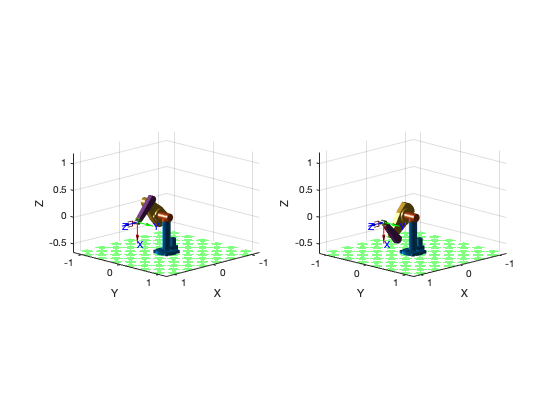

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


subplot(122)
p560.plot3d(qi2)

## Practicing with ikine6s & p560.plot3d(qx)

Display the 8 solutions for qn (joint space). Use subplot 2x2 for elbown up/down and subplot 2x2 for {EE}